# CUDA Time Comparison Analysis

% --Setup
    clear; clc; format compact; close all; warning off;

% --Store Values (10,000 length)

    % --Regular values
        regular_10_median = [10.934, 9.570, 8.802, 8.826, 9.375, 8.189, 8.985, 9.679, 8.951];
        regular_10_mean = [11.436, 9.585, 9.163, 9.219, 10.002, 9.165, 9.394, 9.844, 9.453];
        regular_10_std = [3.163, 1.593, 1.646, 1.750, 2.390, 1.501, 1.807, 2.077, 2.141];
        length_10 = 10000*ones(1,length(regular_10_std));

    % --CUDA Values
        CUDA_10_median = [7.686, 6.821, 6.834, 7.362, 6.781, 7.332, 7.242, 8.351, 7.040];
        CUDA_10_mean = [7.955, 6.954, 6.979, 7.465, 7.202, 8.409, 7.543, 12.549, 7.174];
        CUDA_10_std = [2.123, 1.070, 1.133, 1.424, 2.092, 4.332, 2.114, 7.812, 1.226];

% --Store Values (20,000 length)
    
    % --Regular values
        regular_20_median = [6.181, 6.269, 5.612, 5.597, 6.045];
        regular_20_mean = [7.682, 7.191, 6.604, 6.605, 7.046];
        regular_20_std = [3.792, 3.302, 2.884, 2.929, 3.273];
        length_20 = 20000*ones(1,length(regular_20_mean));
        
    % --CUDA Values
        CUDA_20_median = [7.195, 6.964, 6.568, 6.344, 6.761];
        CUDA_20_mean = [7.847, 7.333, 6.830, 6.415, 7.788];
        CUDA_20_std = [2.934, 2.230, 2.044, 1.324, 3.359];

% --Store Values (30,000 length)

    % --Regular values
        regular_30_median = [11.416, 9.218, 9.181, 9.701, 9.347];
        regular_30_mean = [12.743, 10.486, 10.317, 11.161, 10.186];
        regular_30_std = [4.682, 3.495, 3.505, 3.989, 3.249];
        length_30 = 30000*ones(1, length(regular_30_mean));

    % --CUDA values
        CUDA_30_median = [7.176, 6.784, 6.749, 6.898, 7.406];
        CUDA_30_mean = [7.944, 7.043, 6.830, 7.307, 9.542];
        CUDA_30_std = [2.573, 1.566, 1.137, 1.716, 6.169];

% --Store Values (length = 40,000)
    
    % --Regular values
        regular_40_median = [14.737, 11.790, 12.769, 12.298, 11.661];
        regular_40_mean = [16.430, 13.772, 14.395, 14.214, 13.124];
        regular_40_std = [4.839, 4.200, 4.468, 4.721, 3.888];
        length_40 = 40000*ones(1, length(regular_40_mean));

    % --CUDA values
        CUDA_40_median = [9.078, 6.611, 6.756, 7.702, 6.698];
        CUDA_40_mean = [9.413, 6.825, 6.892, 8.230, 7.162];
        CUDA_40_std = [2.347, 1.213, 0.988, 2.692, 1.402];

% --Store Values (length = 50,000)
    
    % --Regular values
        regular_50_median = [47.294, 38.822, 38.139, 37.604, 42.073];
        regular_50_mean = [49.383, 39.569, 39.881, 39.214, 44.609];
        regular_50_std = [11.087, 7.183, 8.081, 8.029, 10.850];
        length_50 = 50000*ones(1, length(regular_50_mean));

    % --CUDA values
        CUDA_50_median = [16.631, 14.832, 17.743, 14.012, 14.421];
        CUDA_50_mean = [16.661, 14.809, 19.487, 14.178, 14.511, ];
        CUDA_50_std = [1.049, .956, 8.803, 0.751, 0.981];

% --Store Values (length = 60,000)
    
    % --Regular values
        regular_60_median = [56.760, 46.129, 58.232, 58.417, 56.761];
        regular_60_mean = [58.968, 53.471, 57.136, 59.080, 60.049];
        regular_60_std = [16.44, 24.126, 13.588, 16.866, 18.265];
        length_60 = 60000*ones(1, length(regular_60_mean));

    % --CUDA Values
        CUDA_60_median = [15.033, 15.391, 17.167, 22.248, 15.254];
        CUDA_60_mean = [15.694, 15.805, 19.166, 22.068, 16.130];
        CUDA_60_std = [2.751, 1.971, 4.673, 4.435, 2.763];

% --Store Values
   
    % --Regular Values
        regular_80_median = [74.530, 72.583, 73.132, 73.252];
        regular_80_mean = [88.740, 85.408, 85.676, 87.858];
        regular_80_std = [24.635, 23.754, 22.561, 24.162];
        length_80 = 80000*ones(1, length(regular_80_mean));

    % --CUDA values
        CUDA_80_median = [22.874, 16.531, 22.526, 16.713];
        CUDA_80_mean = [22.630, 16.677, 21.896, 17.838];
        CUDA_80_std = [5.353, 1.041, 4.439, 2.890];

% --Store Values (length = 100,000)
    
    % --Regular Values
        regular_100_median = [185.728, 188.019, 207.084, 206.775, 193.558];
        regular_100_mean = [199.416, 199.796, 223.852, 212.594, 201.166];
        regular_100_std = [23, 676, 21.633, 59.893, 28.254, 22.821];
        length_100 = 100000*ones(1, length(regular_100_mean));

    % --CUDA Values
        CUDA_100_median = [33.039, 29.508, 36.196, 35.146, 35.656];
        CUDA_100_mean = [31.717, 31.428, 37.133, 36.208, 36.099];
        CUDA_100_std = [3.525, 4.519, 5.557, 4.919, 2.434];

% --Store Values (length = 150,000)

    % --Regular Values
        regular_150_median = [317.001, 306.995, 326.284, 325.767, 307.381];
        regular_150_mean = [318.431, 320.436, 321.549, 323.486, 318.696];
        regular_150_std = [23.925, 29.430, 24.786, 26.006, 27.788];
        length_150 = 150000*ones(1, length(regular_150_mean));

    % --CUDA Values
        CUDA_150_median =[56.300, 55.914, 55.434, 55.721, 55.723];
        CUDA_150_mean = [57.628, 56.682, 55.191, 55.835, 55.211];
        CUDA_150_std = [4.228, 4.942, 5.420, 2.511, 4.265];

% --Creating line sets for data regression
    regular_means = [regular_10_mean, regular_20_mean, regular_30_mean, regular_40_mean,...
        regular_50_mean, regular_60_mean, regular_80_mean, regular_100_mean, regular_150_mean];
    CUDA_means = [CUDA_10_mean, CUDA_20_mean, CUDA_30_mean, CUDA_40_mean, CUDA_50_mean, CUDA_60_mean ...
        CUDA_80_mean, CUDA_100_mean, CUDA_150_mean];
    lengths = [length_10, length_20, length_30, length_40, length_50, length_60, length_80, length_100, length_150];

% --Plot
    figure()
    plot(lengths, regular_means,'.', 'Color', [0.8 0.2 0.2])
        hold on
        xlim([10000 150000])
        ylim([0 350])
        grid on
        xlabel('Data Set Length (N samples)')
        ylabel('Benchmark Simulation Mean Time (ms)')
        title('Benchmark Time Test of Kernel Cross Correlator')
    plot(lengths, CUDA_means, '.', 'Color', [0.2 0.2 0.8])

% --Fit the regression
    p = polyfit(lengths, regular_means, 2)

p =     0.0000    0.0005   -7.5567


    x1 = 0:100:150000;
    f1 = polyval(p,x1);
    plot(x1,f1, 'Color', [0.8 0.2 0.2])

% --CUDA fit regression
    p = polyfit(lengths, CUDA_means, 1)

p =     0.0003   -0.7401


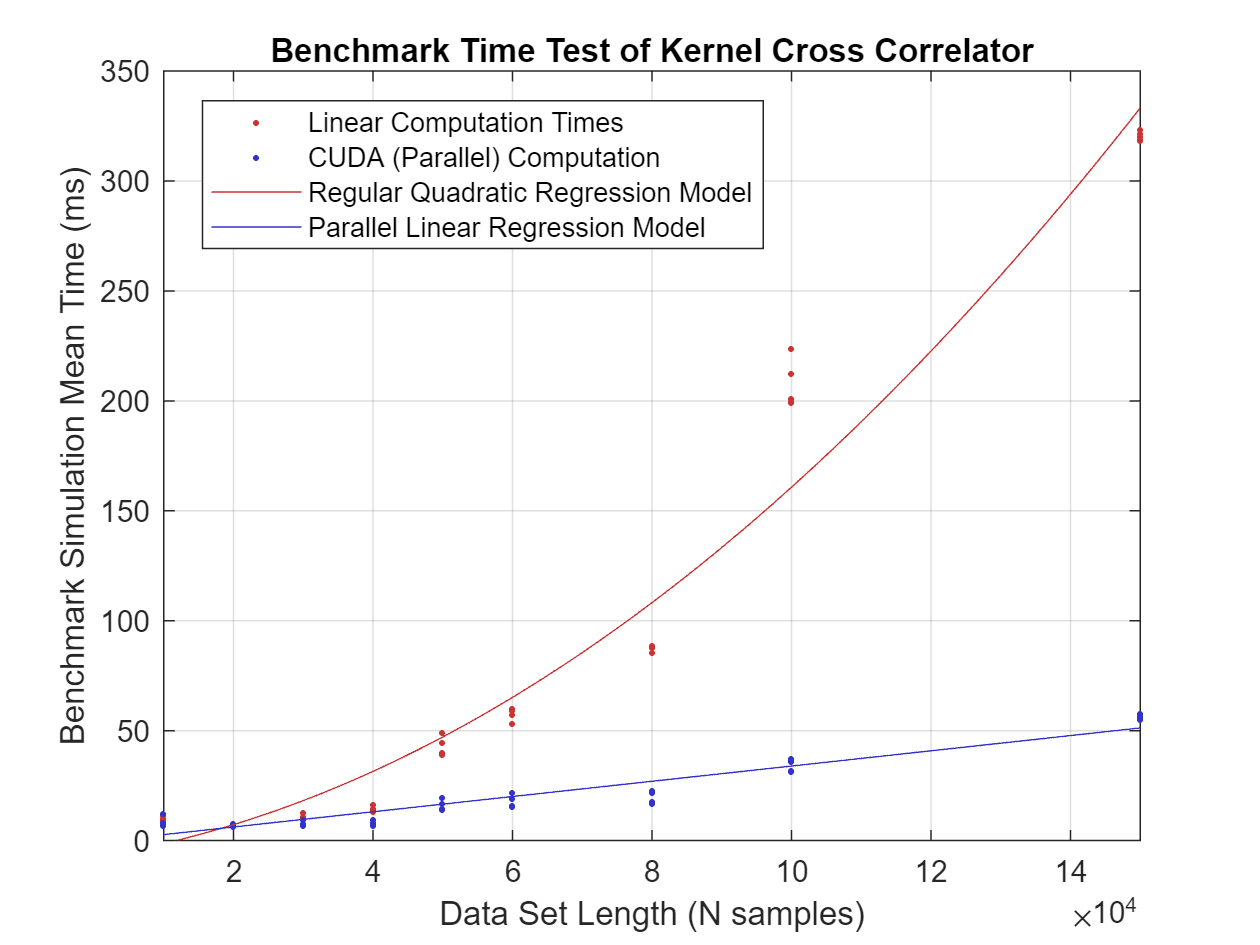

    x1 = 0:100:150000;
    f1 = polyval(p,x1);
    plot(x1,f1, 'Color', [0.2 0.2 0.8])
    legend('Linear Computation Times', 'CUDA (Parallel) Computation', 'Regular Quadratic Regression Model', 'Parallel Linear Regression Model')
    legend("Position", [0.16072,0.73706,0.44464,0.15595])

% --Fitlm
    fitlm(lengths, CUDA_means, "linear")

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________
    (Intercept)       -0.7401       1.0655    -0.69463       0.49078
    x1             0.00034656    1.526e-05       22.71    1.2294e-26

Number of observations: 48, Error degrees of freedom: 46
Root Mean Squared Error: 4.49
R-squared: 0.918,  Adjusted R-Squared: 0.916
F-statistic vs. constant model: 516, p-value = 1.23e-26

    fitlm(lengths, regular_means, "quadratic")

ans = Linear regression model:
    y ~ 1 + x1 + x1^2

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________
    (Intercept)       -7.5567        7.1199    -1.0614       0.29419
    x1             0.00050545    0.00024026     2.1038      0.041017
    x1^2           1.1777e-08    1.5183e-09     7.7568    7.8063e-10

Number of observations: 48, Error degrees of freedom: 45
Root Mean Squared Error: 19.6
R-squared: 0.965,  Adjusted R-Squared: 0.964
F-statistic vs. constant model: 624, p-value = 1.54e-33